% initSim
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f*Lbase1v

L_f = 1.7849e-05

R_f = r_f*Zbase1v

R_f = 0.0013

C_f = 0.0757204*Cbase1v

C_f = 0.0011

c_f = 0.0757

c_f = 0.0757

% plant
    
G_plant = 1/(s*l_f/omega_nom+r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


T_delay = 0.1e-3

T_delay = 1.0000e-04

% G_sensor = 1/(1+s*T_delay)
G_i = G_plant;%*G_sensor

% f_sw = 10000
f_c = 1/5*f_sw

f_c = 590



Kp_cc =  1.33      

Kp_cc = 1.3300

Ti_cc =  0.005

Ti_cc = 0.0050

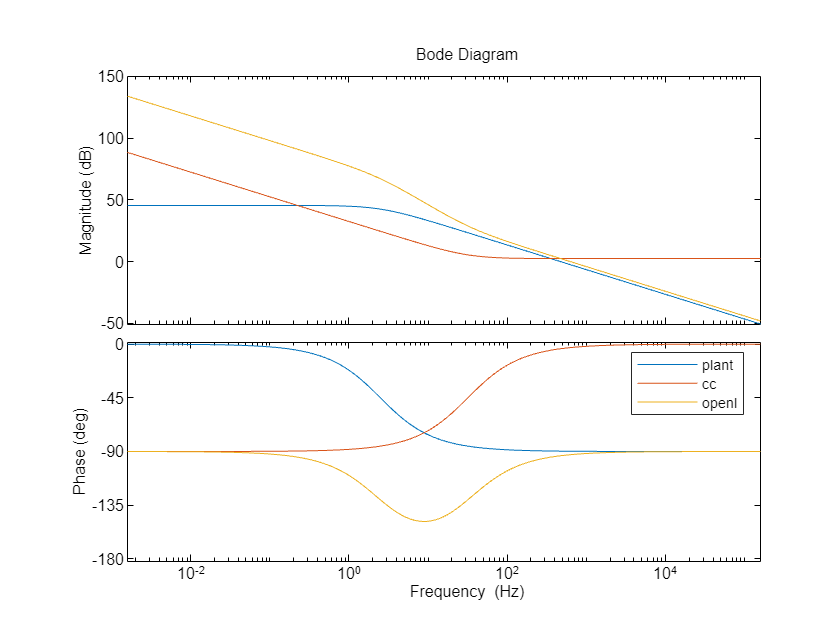

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)  
G_cc = Kp_cc*(1 + s*Ti_cc)/(s*Ti_cc);
% Kp_cc*(1+1/Ti_cc/s)

% Ki_cc = Kp_cc/Ti_cc

% Kp_cc+Ki_cc/s

G_openl = G_cc*G_i;


options = bodeoptions;
options.FreqUnits = 'Hz'; % or 'rad/second', 'rpm', etc.
options.PhaseWrapping='on';


bode(G_i,G_cc,G_openl,{10e-3,10e5}, options)
legend('plant', 'cc','openl')

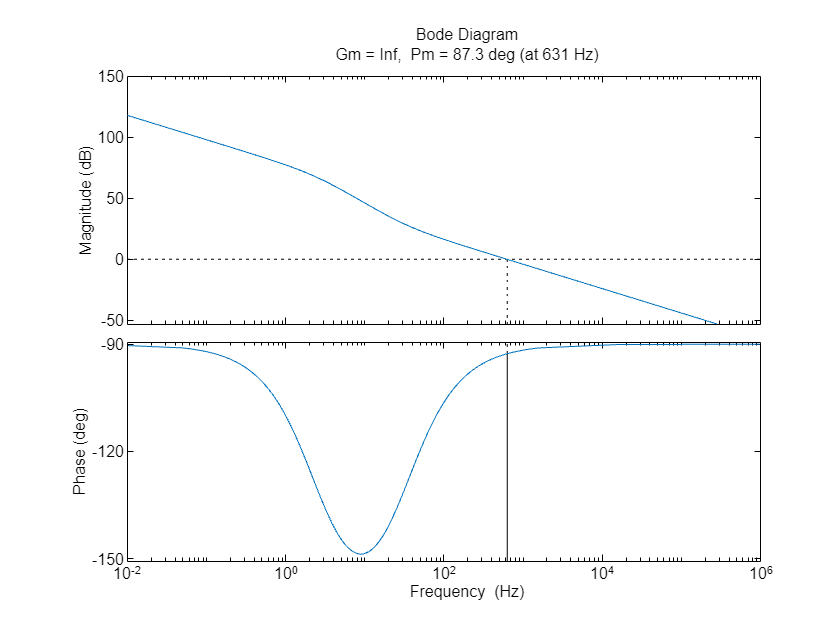

% bode(G_cc/(1+G_cc),{10e-3,10e5})

options.XLim = [10e-3,10e5];
% 
margin(G_openl,options)

% margin(G_cl)
G_cl = G_openl/(1+G_openl)

G_cl =
 
         0.001103 s^3 + 0.2379 s^2 + 3.465 s
  --------------------------------------------------
  2.787e-07 s^4 + 0.001112 s^3 + 0.238 s^2 + 3.465 s
 
Continuous-time transfer function.
Model Properties


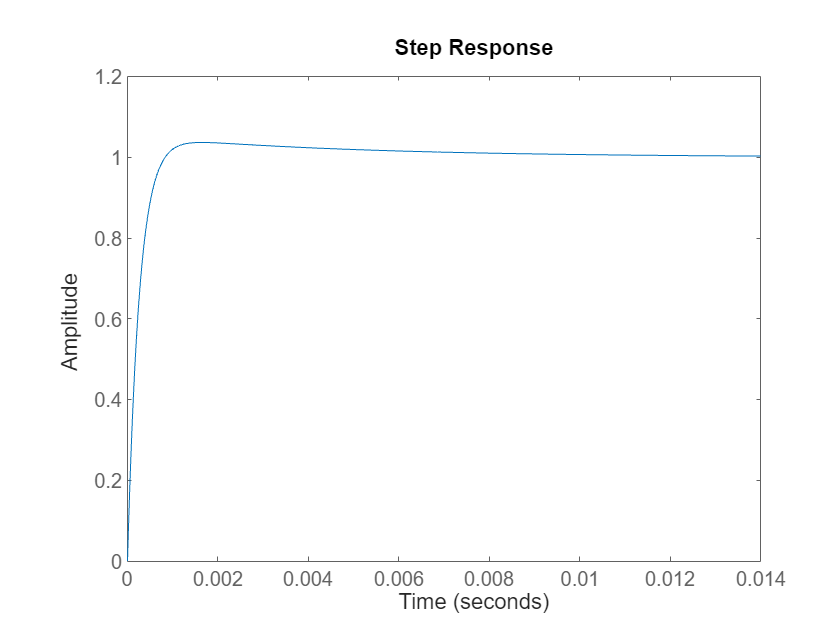

step(G_cl)

% pzmap(G_cl)

T_ers = 1/(2*pi*f_c)

T_ers = 2.6975e-04

Gapprox = 1/(1+s*T_ers)

Gapprox =
 
         1
  ---------------
  0.0002698 s + 1
 
Continuous-time transfer function.
Model Properties


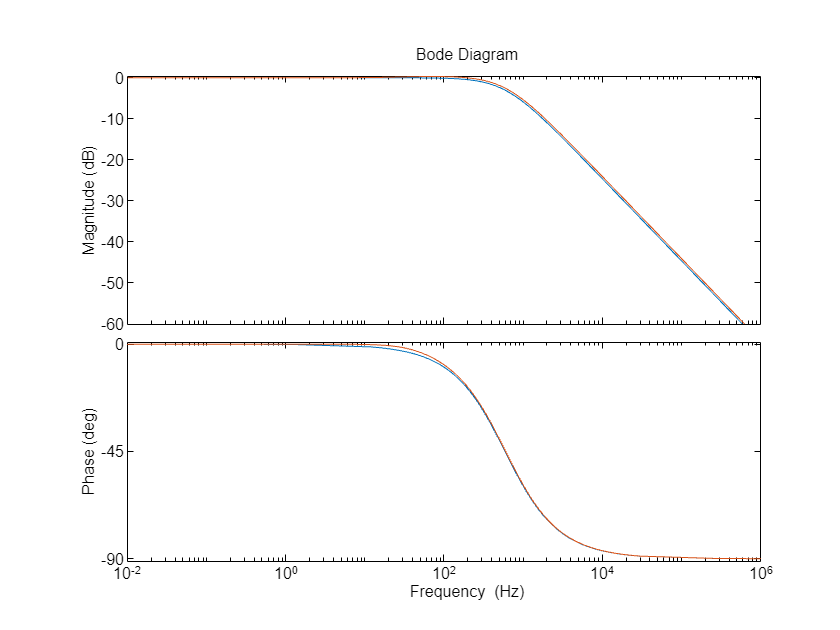

bode(Gapprox,G_cl,options)

% P0 = Sbase1
% p_1 = -1/T_ers
% z_1 = 3*Vbase_lv^2/(2*L_f*P0)
% UDC = V_dc
% UNd = Vbase_lv
% C = C_f
% L = L_f
% 
Gu=1/(s*c_f/omega_nom);%(3/2*UNd-s*L*P0/UNd)/(s*UDC*C);
Gstr=Gapprox*Gu;


% z = 20
% asind((1-T_ers*z)/(1+T_ers*z)) % phase margin
% omega_c_vc = sqrt(z/T_ers)
% k_vc = (c_f/omega_nom)*omega_c_vc
% G_vc = k_vc*(s+z)/s
% %open
% G_forward_vc = k_vc/(ti*(c_f/omega_nom))*((s+z)/(s+1/ti))*1/s^2
% margin(G_forward_vc)
% % closed
% T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)
% step(T_vc)
    % pzmap(T_vc)


kpu=0.32;
Tnu=0.007;
Gcu=kpu*(1+s*Tnu)/(s*Tnu)

Gcu =
 
  0.00224 s + 0.32
  ----------------
      0.007 s
 
Continuous-time transfer function.
Model Properties


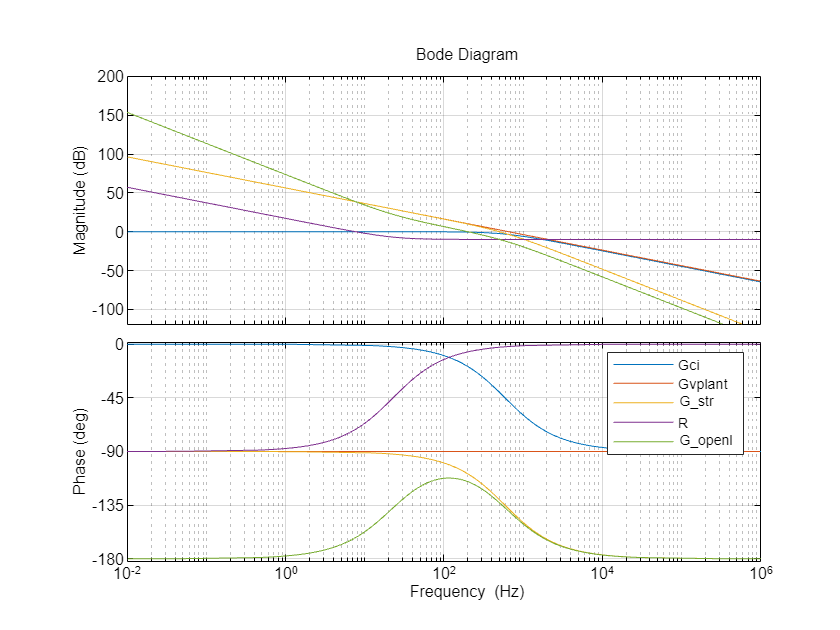


Golu=Gcu*Gstr;
Gclu=Golu/(1+Golu); 

figure(3);
bode(Gapprox, Gu, Gstr,Gcu,Golu,options);
legend('Gci', 'Gvplant', 'G_{str}','R','G_{openl}');
grid on;

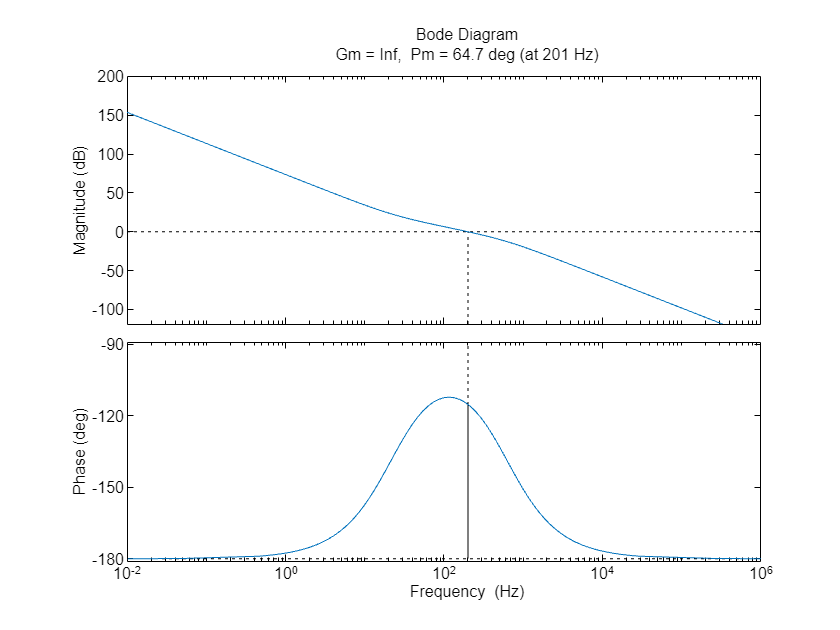

figure(4);
margin(Golu,options)

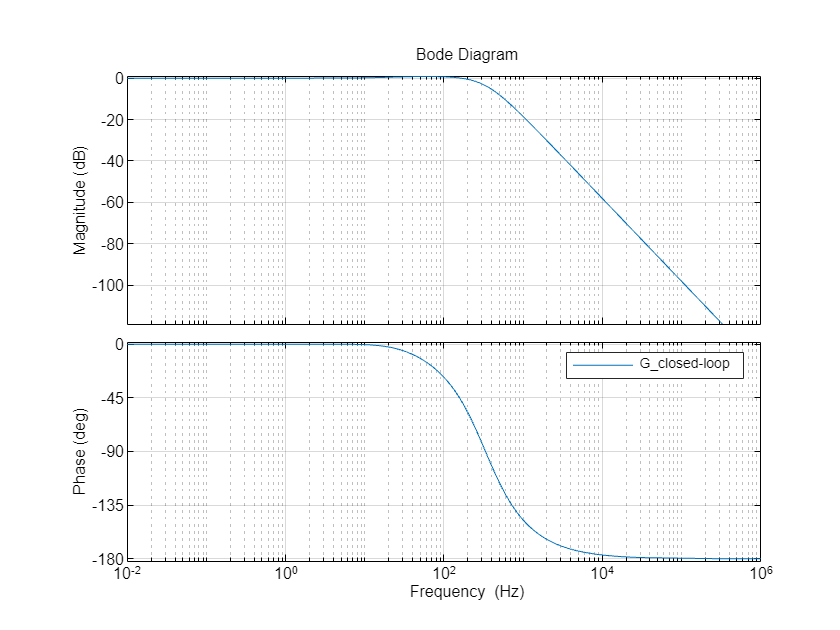

figure(5);
bode(Gclu,options);
legend('G_{closed-loop}');
grid on;


% Kp_vc =  40 %C_f/Tau_cc % % 0.05%1/Vbase_lv;C_f*omega_v %
% Ki_vc =  200 % 2*Kp_vc*omega_v^2/omega_c% 2*Kp_vc*Tau_cc%    %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 


% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
% G_vc = Kp_vc + Ki_vc/s

G_vc =
 
  40 s + 200
  ----------
      s
 
Continuous-time transfer function.
Model Properties


% 
% G_openl = G_vc*G_cc*G_plant

G_openl =
 
  0.00312 s^2 + 2.416 s + 12
  --------------------------
         2.32e-08 s^3
 
Continuous-time transfer function.
Model Properties


% G_cl = G_openl/(1+G_openl)

G_cl =
 
          7.24e-11 s^5 + 5.605e-08 s^4 + 2.784e-07 s^3
  ------------------------------------------------------------
  5.384e-16 s^6 + 7.24e-11 s^5 + 5.605e-08 s^4 + 2.784e-07 s^3
 
Continuous-time transfer function.
Model Properties



% bode(G_plant,G_cc,G_vc,G_openl,{10e-3,10e5})
% legend('plant', 'cc','vc','openl')
% 
% margin(G_vc)
% bode(G_vc,G_cc,{10e-3,10e5})
% 
% step(G_cl)
% pzmap(G_cl)


G_dcplant = 1/(s*(2*c_dc/omega_nom))

G_dcplant =
 
     1
  -------
  0.003 s
 
Continuous-time transfer function.
Model Properties


kp_dc = 5;
Ti_dc = 0.004;
G_dcpi = kp_dc*(1+s*Ti_dc)/(s*Ti_dc)

G_dcpi =
 
  0.02 s + 5
  ----------
   0.004 s
 
Continuous-time transfer function.
Model Properties



G_dc_openloop = G_dcpi*G_dcplant

G_dc_openloop =
 
  0.02 s + 5
  -----------
  1.2e-05 s^2
 
Continuous-time transfer function.
Model Properties


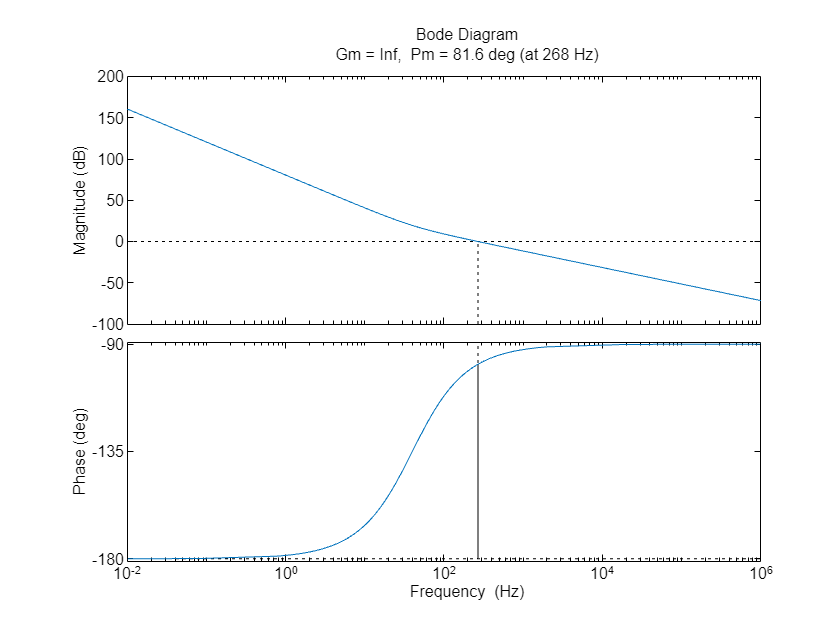

margin(G_dc_openloop,options)


G_dc_closed = G_dc_openloop/(1+G_dc_openloop)

G_dc_closed =
 
         2.4e-07 s^3 + 6e-05 s^2
  --------------------------------------
  1.44e-10 s^4 + 2.4e-07 s^3 + 6e-05 s^2
 
Continuous-time transfer function.
Model Properties


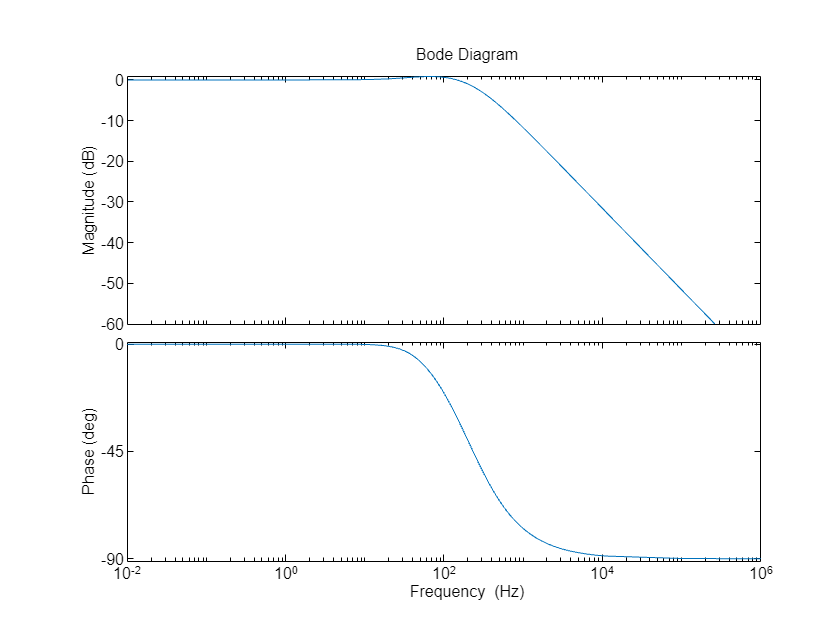

bode(G_dc_closed,options)

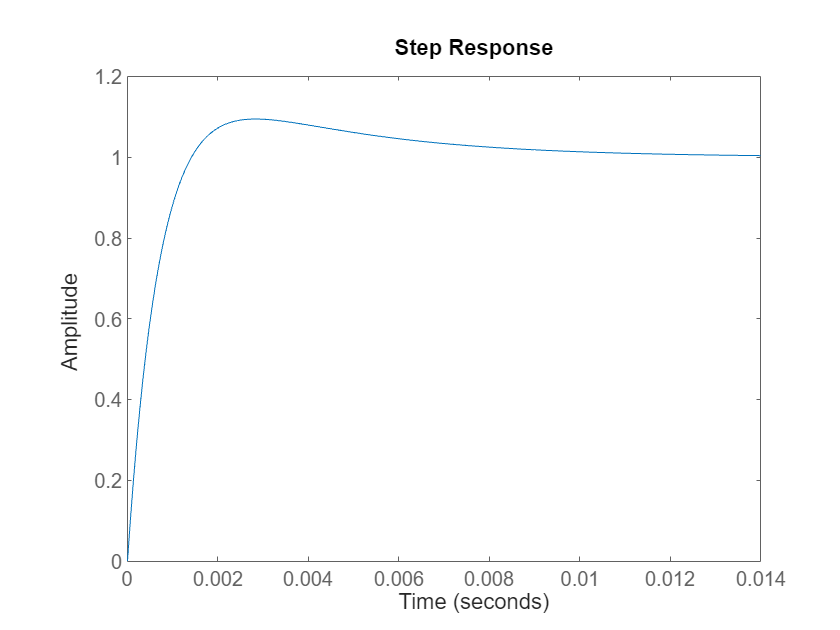

step(G_dc_closed)

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

    % kp_p = (0.95-1)/(0.5-1)%0.05
    % 
    % % (vmeas-vref)/(Qref-Qmeas) = -kp_q
    % kp_q = (0.9-1)/(0-0.5)

% (5+0.4/s)/(1-5+0.4/s)
% 
% bode((5+0.4/s)/(1+5+0.4/s))
% 

% c_f=0.07
% H=omega_c/2
% tau_dcc = 2*L_f/3*Sbase1/Vbase_lv^2
% G_dc = -(2/C_f)*(tau_dcc*s+1)/s
% G_cc = 1/(0.005*s+1)
% K_v =C_f/2*H/s
% loop_gain = K_v*G_cc*G_dc
% bode(loop_gain)
% margin(H)
% loop_gain/(1-loop_gain)
% margin(loop_gain/(1-loop_gain))
% 
% 
% 1/0.005*2*pi

## dc

% 
% omega_dc = 2*pi*20
% R_dc = V_dc^2/Sbase1
% Kp_dcc = omega_dc*C_dc
% Ki_dcc = omega_dc       
% 
% 
options.PhaseWrapping='off';


% ti = 1/f_c

ti = 0.0020

% f_dc = f_c/5

f_dc = 100

% f_dc*2*pi

ans = 628.3185

% G_i_dc = (0.01*s+1)/(s*0.01)

G_i_dc =
 
  0.01 s + 1
  ----------
    0.01 s
 
Continuous-time transfer function.
Model Properties


% (1/0.01)/(1/0.01+s)

ans =
 
    100
  -------
  s + 100
 
Continuous-time transfer function.
Model Properties


% tau_plant = 2/3*L_f*1*Sbase1/Vbase_lv^2

tau_plant = 5.6235e-05

% G_p_dc = -(2/C_f)*(tau_plant*s+1)/s

G_p_dc =
 
  -0.09874 s - 1756
  -----------------
          s
 
Continuous-time transfer function.
Model Properties


% G_dc_plant = G_i_dc*G_p_dc

G_dc_plant =
 
  -0.0009874 s^2 - 17.66 s - 1756
  -------------------------------
             0.01 s^2
 
Continuous-time transfer function.
Model Properties


% ks = 225        

ks = 225

% ki = 1

ki = 1

% Gdc = -ks/s

Gdc =
 
  -225
  ----
   s
 
Continuous-time transfer function.
Model Properties


% G_dc_openl = Gdc*G_dc_plant

G_dc_openl =
 
  0.2222 s^2 + 3973 s + 3.951e05
  ------------------------------
             0.01 s^3
 
Continuous-time transfer function.
Model Properties


% n0 = 1/(10^(-23/20))

n0 = 14.1254

% 
% a = 200

a = 200

% p = sqrt(a)*2*pi*f_dc

p = 8.8858e+03

% N = n0*(s+p/a)/(s+p)

N =
 
  14.13 s + 627.6
  ---------------
     s + 8886
 
Continuous-time transfer function.
Model Properties


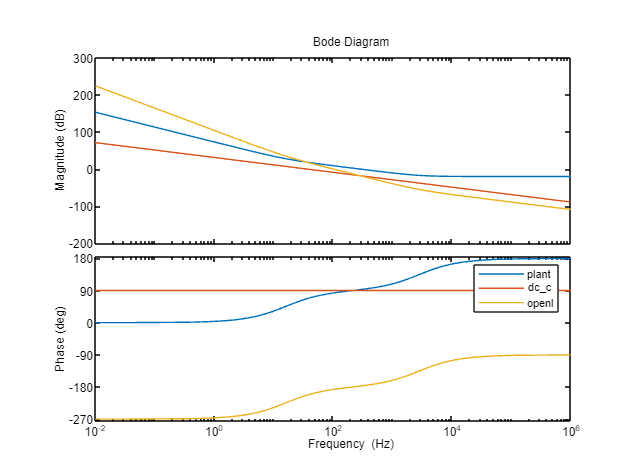

% 
% bode(G_dc_plant,Gdc,G_dc_openl,options)
% legend('plant', 'dc_c','openl')

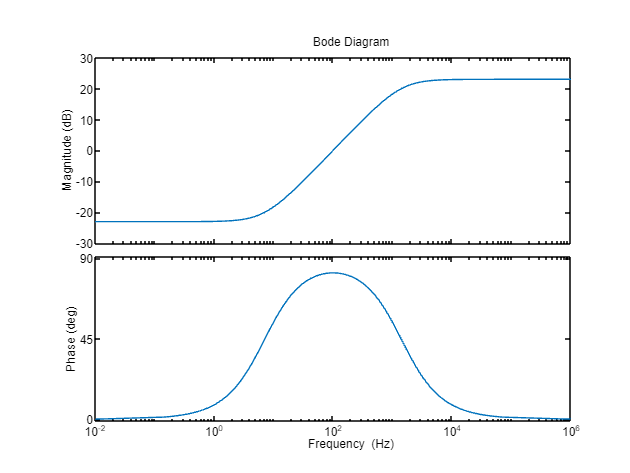

% bode(N,options)

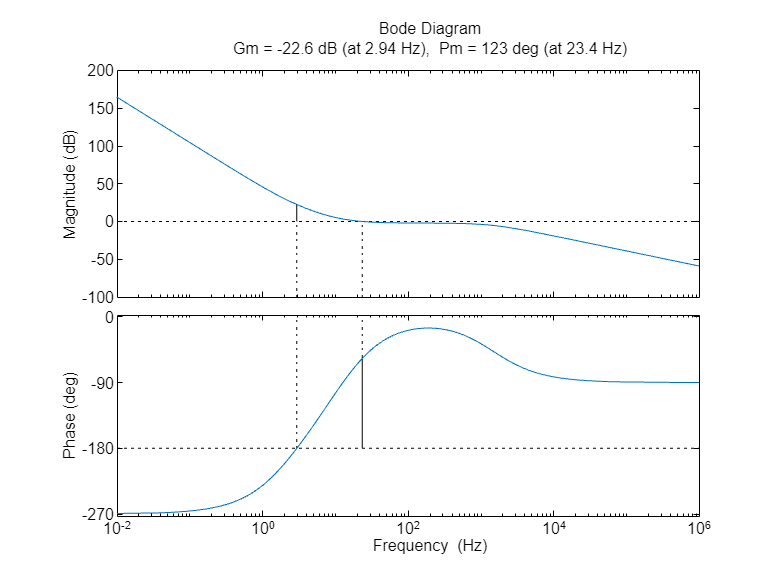

% margin(N*G_dc_openl,options)

% N*G_dc

ans =
 
  1.059e05 s^2 + 4.707e06 s + 2.353e04
  ------------------------------------
              s^2 + 8886 s
 
Continuous-time transfer function.
Model Properties
